% close all open figures
close all

% Clear the workspace and command window
clear; clc;

%% GPU Setup
parallel.gpu.enableCUDAForwardCompatibility(true)
gpuDevice

ans =   CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 5060 Laptop GPU'
                Index: 1 (of 1)
    ComputeCapability: '12.0'
          DriverModel: 'WDDM'
          TotalMemory: 8546484224 (8.55 GB)
      AvailableMemory: 7283408896 (7.28 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

%% Load Dataset
imds = imageDatastore('color','IncludeSubfolders',true,'LabelSource','foldernames');

% Total number of Images and Classes in Dataset
numImages = numel(imds.Files)

numImages = 54305

numClasses = numel(categories(imds.Labels))

numClasses = 38

% Total number of images in each class
labelCount = countEachLabel(imds)

labelCount = 38×2 table
                          Label                           Count
    __________________________________________________    _____

    Apple___Apple_scab                                     630 
    Apple___Black_rot                                      621 
    Apple___Cedar_apple_rust                               275 
    Apple___healthy                                       1645 
    Blueberry___healthy                                   1502 
    Cherry_(including_sour)___Powdery_mildew              1052 
    Cherry_(including_sour)___healthy                      854 
    Corn_(maize)___Cercospora_leaf_spot Gray_leaf_spot     513 
    Corn_(maize)___Common_rust_                           1192 
    Corn_(maize)___Northern_Leaf_Blight                    985 
    Corn_(maize)___healthy                                1162 
    Grape___Black_rot                                     1180 
    Grape__

% image sizes 
img = readimage(imds,1); size(img)

ans =    256   256     3


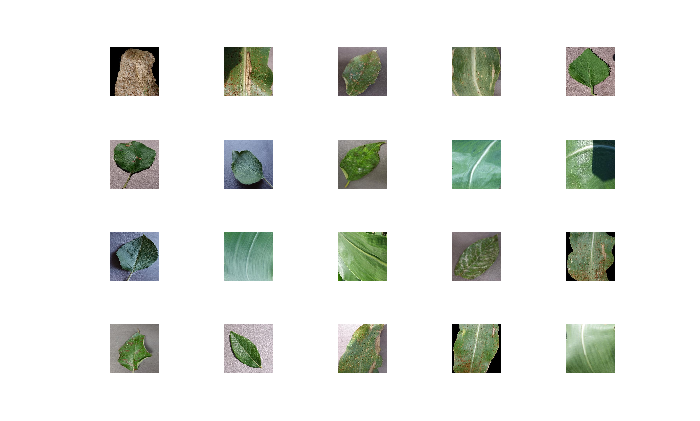

% Display some of the images in the datastore
figure; 
perm = randperm(10000,20); for i = 1:20 
    subplot(4,5,i); imshow(imds.Files{perm(i)}); 
end

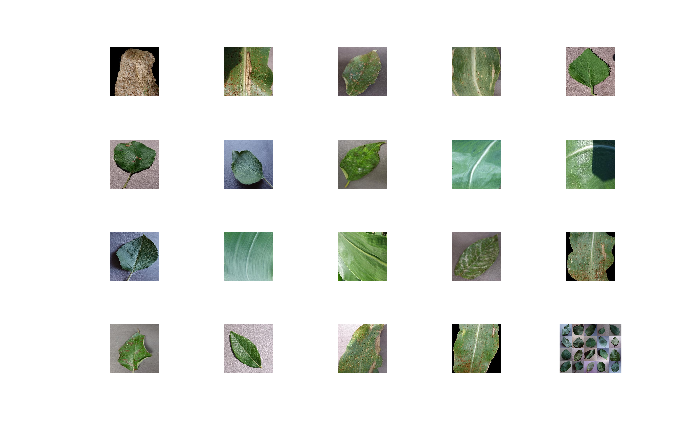

% View images that belong to a specific class
numObsToShow = 20;
class = "Apple___healthy";
idxClass = find(imds.Labels == class);
idx = randsample(idxClass,numObsToShow);
imshow(imtile(imds.Files(idx),'GridSize',[4,5],'ThumbnailSize',[100,100]));

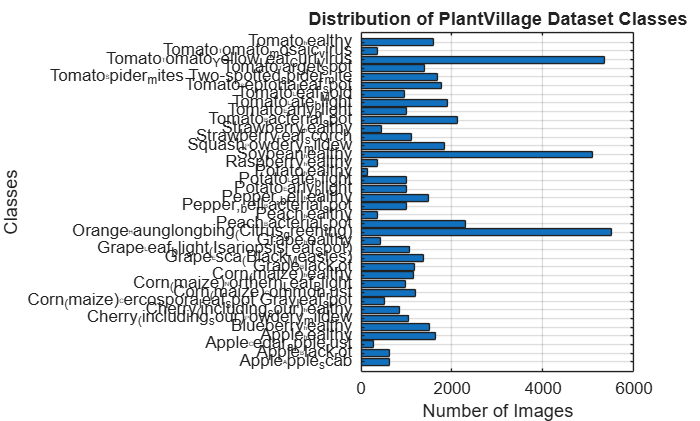

% visualize the distribution of the class labels using a histogram
labelTable = countEachLabel(imds);

figure
barh(labelTable.Count)
yticks(1:height(labelTable))
yticklabels(labelTable.Label)

xlabel("Number of Images")
ylabel("Classes")
title("Distribution of PlantVillage Dataset Classes")
grid on

% Split Dataset
[imdsTrain, imdsValidation, imdsTest] = splitEachLabel(imds,0.7,0.15,0.15,'randomized');

numClasses = numel(categories(imds.Labels));

%% Store Results
results = struct;


%% =========================
%% 1. CUSTOM CNN
%% =========================

augTrain_cnn = augmentedImageDatastore([256 256], imdsTrain);
augValidation_cnn = augmentedImageDatastore([256 256], imdsValidation);
augTest_cnn = augmentedImageDatastore([256 256], imdsTest);

layers = [
imageInputLayer([256 256 3],'Normalization','zerocenter')

convolution2dLayer(3,32,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)

convolution2dLayer(3,64,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)

convolution2dLayer(3,128,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)

convolution2dLayer(3,256,'Padding','same')
batchNormalizationLayer
reluLayer
maxPooling2dLayer(2,'Stride',2)

fullyConnectedLayer(256)
reluLayer
dropoutLayer(0.5)

fullyConnectedLayer(numClasses)
softmaxLayer
classificationLayer
];

options_cnn = trainingOptions('adam',...
    'ExecutionEnvironment','gpu',...
    'InitialLearnRate',1e-4,...
    'MaxEpochs',15,...
    'MiniBatchSize',32,...
    'Shuffle','every-epoch',...
    'ValidationData',augValidation_cnn,...
    'ValidationFrequency',50,...
    'Plots','training-progress',...
    'Verbose',false);

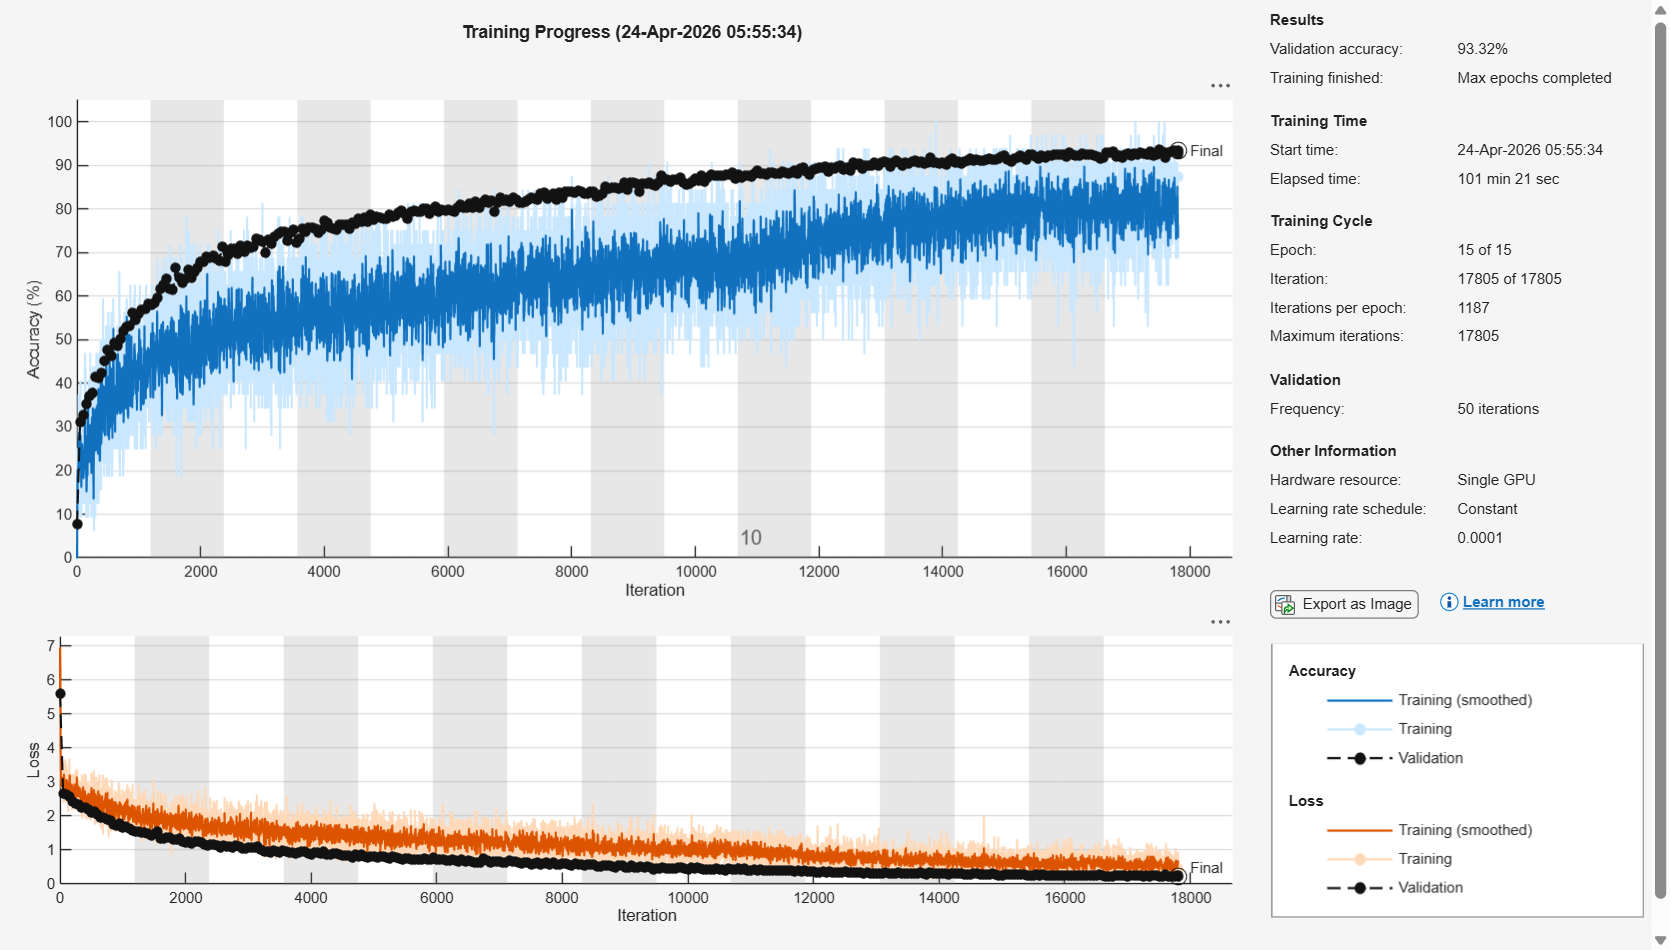

[cnnModel,info] = trainNetwork(augTrain_cnn,layers,options_cnn);

[YPred,scores] = classify(cnnModel,augTest_cnn);
YTest = imdsTest.Labels;

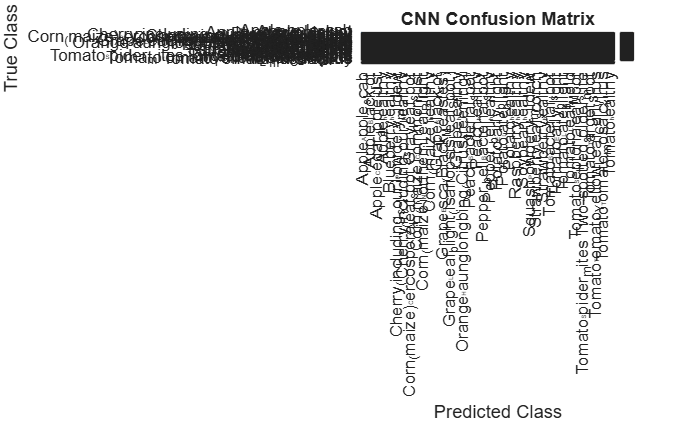

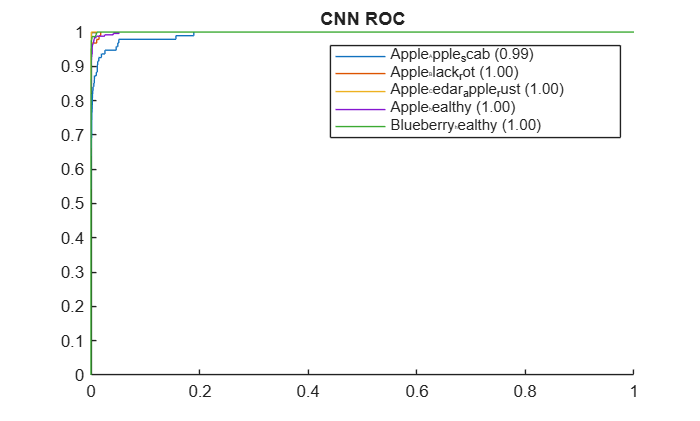

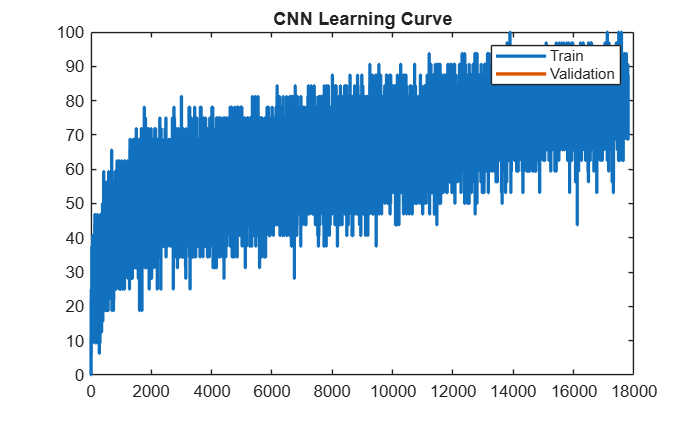

results.CNN = evaluateModel(YPred,YTest,scores,'CNN',info);

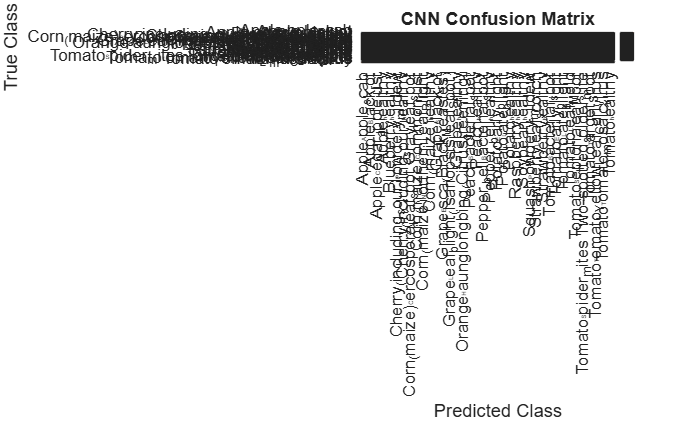

figure('Name','CNN Confusion Matrix','NumberTitle','off');
cm = confusionchart(YTest, YPred);
cm.Title = 'CNN Confusion Matrix';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

save('CNN_Model.mat','cnnModel')

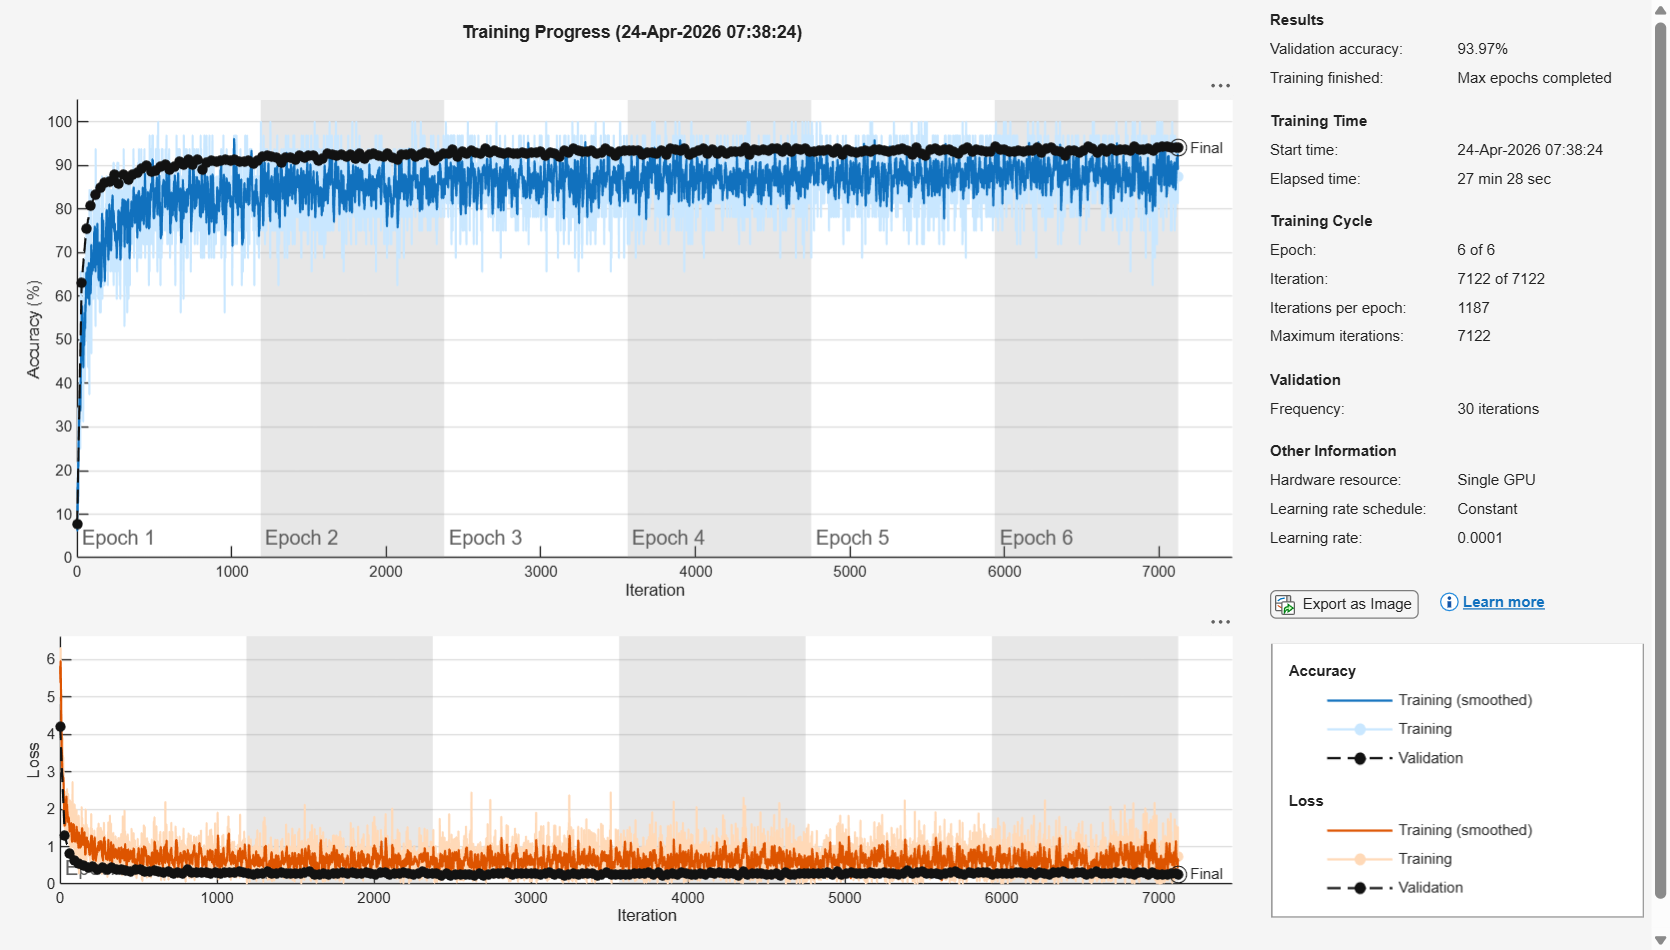

%% =========================
%% 2. ALEXNET
%% =========================

net = alexnet;

layersTransfer = net.Layers(1:end-3);

% Freeze early layers
for i = 1:numel(layersTransfer)
    if isprop(layersTransfer(i),'WeightLearnRateFactor')
        layersTransfer(i).WeightLearnRateFactor = 0;
        layersTransfer(i).BiasLearnRateFactor = 0;
    end
end

layers = [
layersTransfer
fullyConnectedLayer(numClasses,'WeightLearnRateFactor',10)
softmaxLayer
classificationLayer];

augTrain_alex = augmentedImageDatastore([227 227], imdsTrain);
augValidation_alex = augmentedImageDatastore([227 227], imdsValidation);
augTest_alex = augmentedImageDatastore([227 227], imdsTest);

options_alex = trainingOptions('adam',...
    'ExecutionEnvironment','gpu',...
    'InitialLearnRate',1e-4,...
    'MaxEpochs',6,...
    'MiniBatchSize',32,...
    'Shuffle','every-epoch',...
    'ValidationData',augValidation_alex,...
    'ValidationFrequency',30,...
    'Plots','training-progress',...
    'Verbose',false);

[alexModel,info] = trainNetwork(augTrain_alex,layers,options_alex);

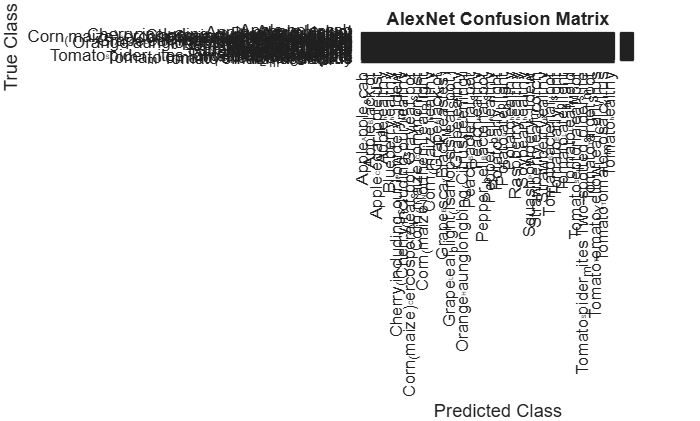

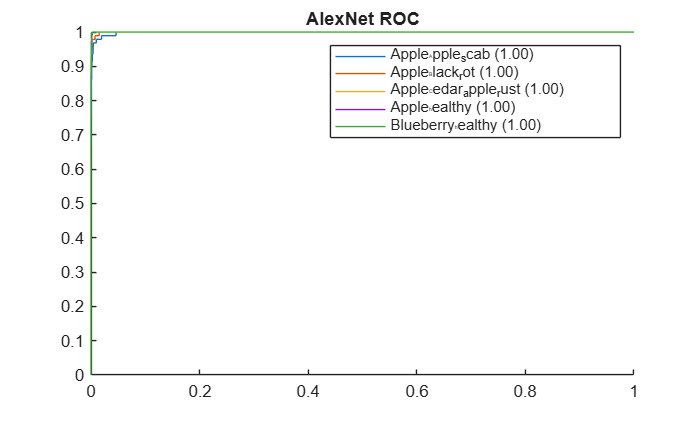

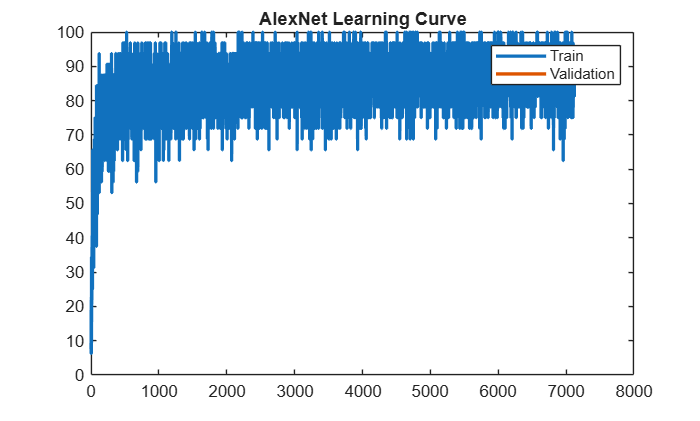


[YPred,scores] = classify(alexModel,augTest_alex);
results.AlexNet = evaluateModel(YPred,YTest,scores,'AlexNet',info);

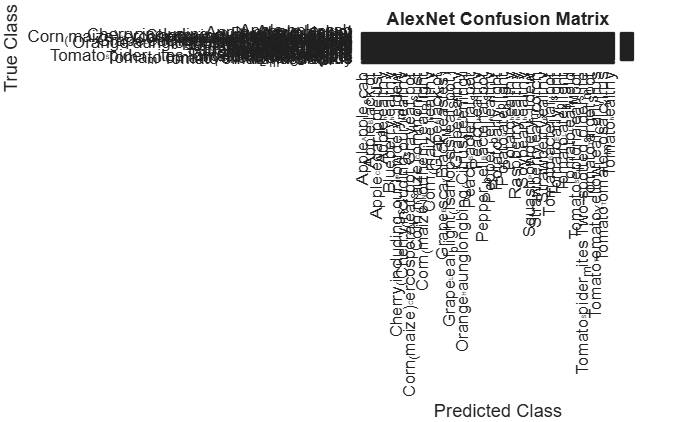

figure('Name','AlexNet Confusion Matrix','NumberTitle','off');
cm = confusionchart(YTest, YPred);
cm.Title = 'AlexNet Confusion Matrix';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

save('AlexNet_Model.mat','alexModel')

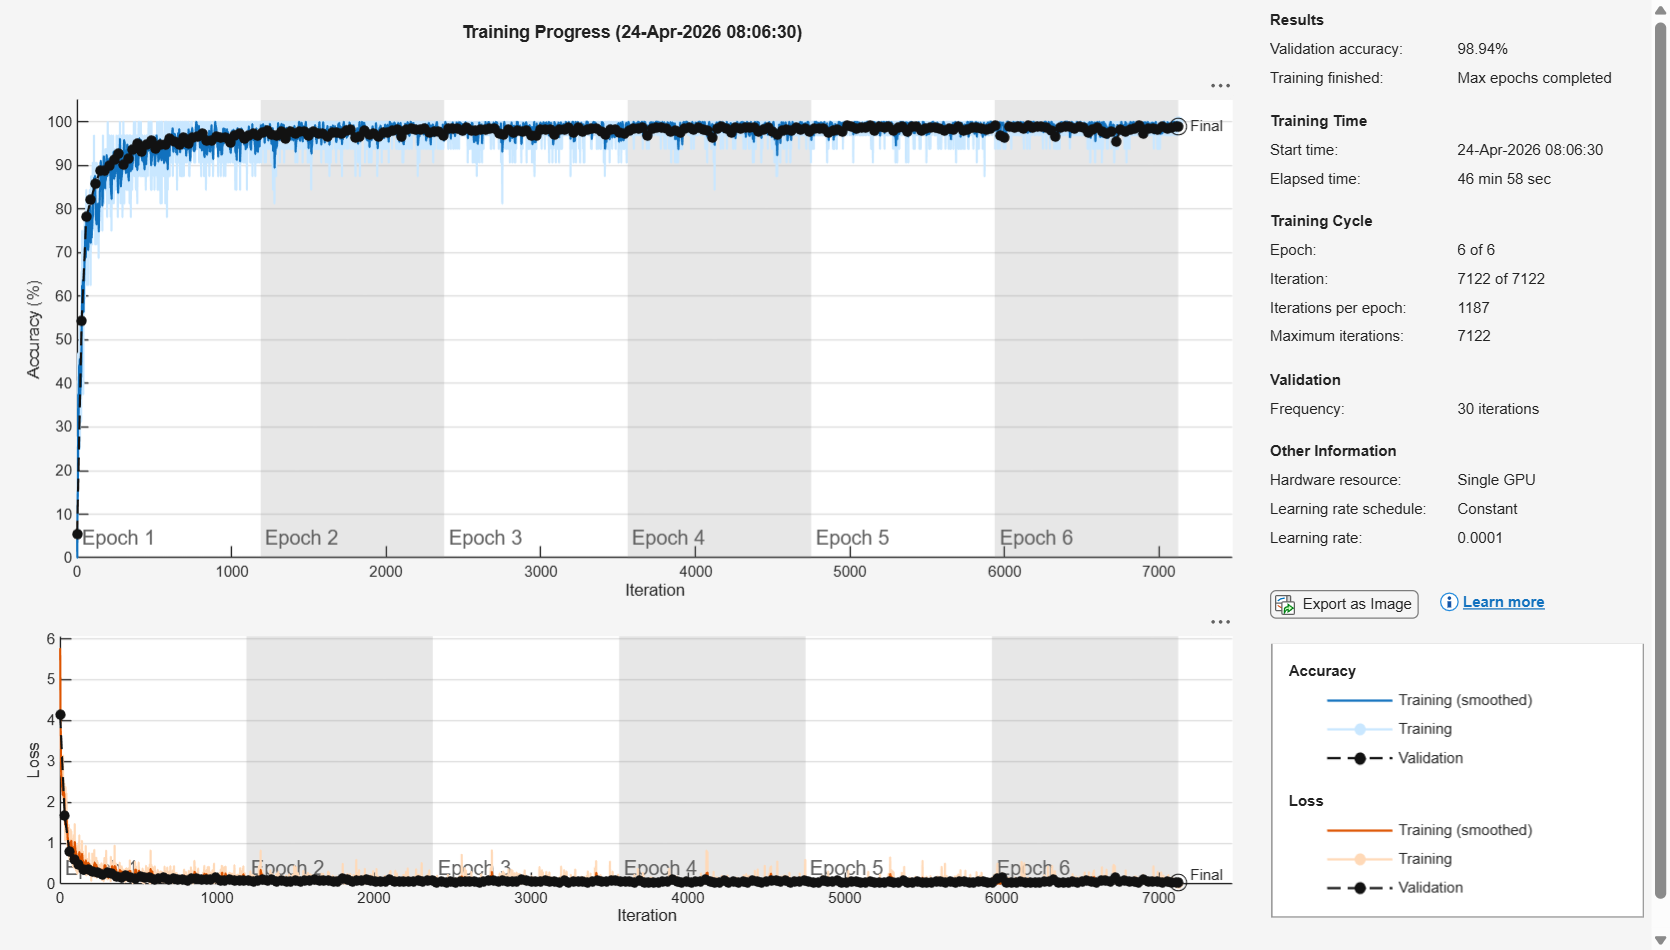

%% =========================
%% 3. GOOGLENET
%% =========================

net = googlenet;
lgraph = layerGraph(net);

newLayers = [
fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10)
softmaxLayer('Name','new_softmax')
classificationLayer('Name','new_classoutput')];

lgraph = replaceLayer(lgraph,'loss3-classifier',newLayers(1));
lgraph = replaceLayer(lgraph,'prob',newLayers(2));
lgraph = replaceLayer(lgraph,'output',newLayers(3));

augTrain_google = augmentedImageDatastore([224 224], imdsTrain);
augValidation_google = augmentedImageDatastore([224 224], imdsValidation);
augTest_google = augmentedImageDatastore([224 224], imdsTest);

options_google = trainingOptions('adam',...
    'ExecutionEnvironment','gpu',...
    'InitialLearnRate',1e-4,...
    'MaxEpochs',6,...
    'MiniBatchSize',32,...
    'Shuffle','every-epoch',...
    'ValidationData',augValidation_google,...
    'ValidationFrequency',30,...
    'Plots','training-progress',...
    'Verbose',false);

[googleModel,info] = trainNetwork(augTrain_google,lgraph,options_google);

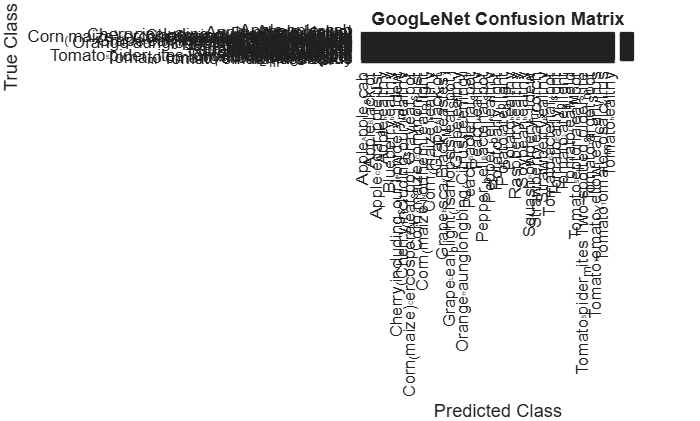

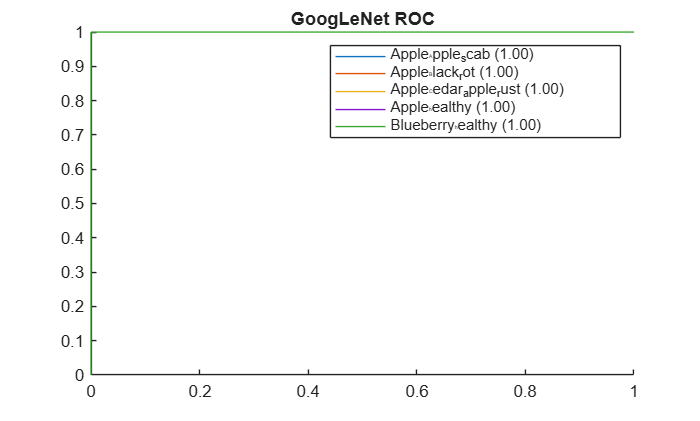

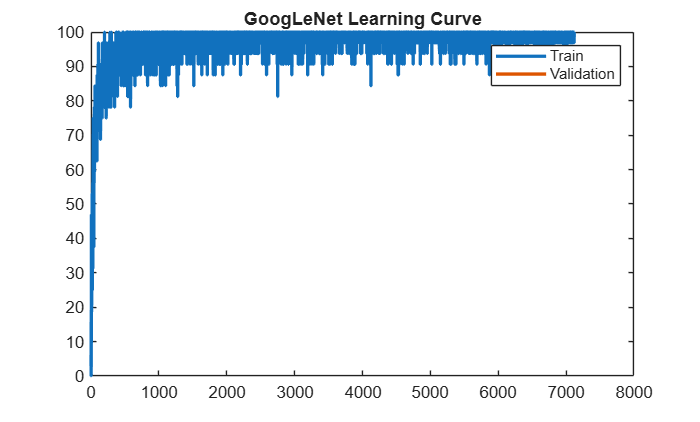


[YPred,scores] = classify(googleModel,augTest_google);
results.GoogLeNet = evaluateModel(YPred,YTest,scores,'GoogLeNet',info);

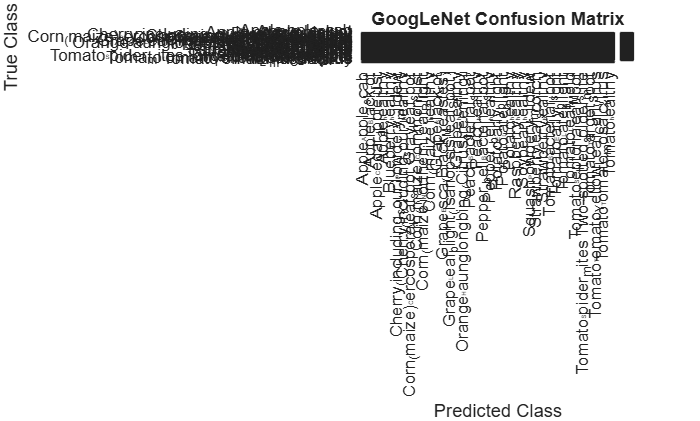

figure('Name','GoogLeNet Confusion Matrix','NumberTitle','off');
cm = confusionchart(YTest, YPred);
cm.Title = 'GoogLeNet Confusion Matrix';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

save('GoogleNet_Model.mat','googleModel')

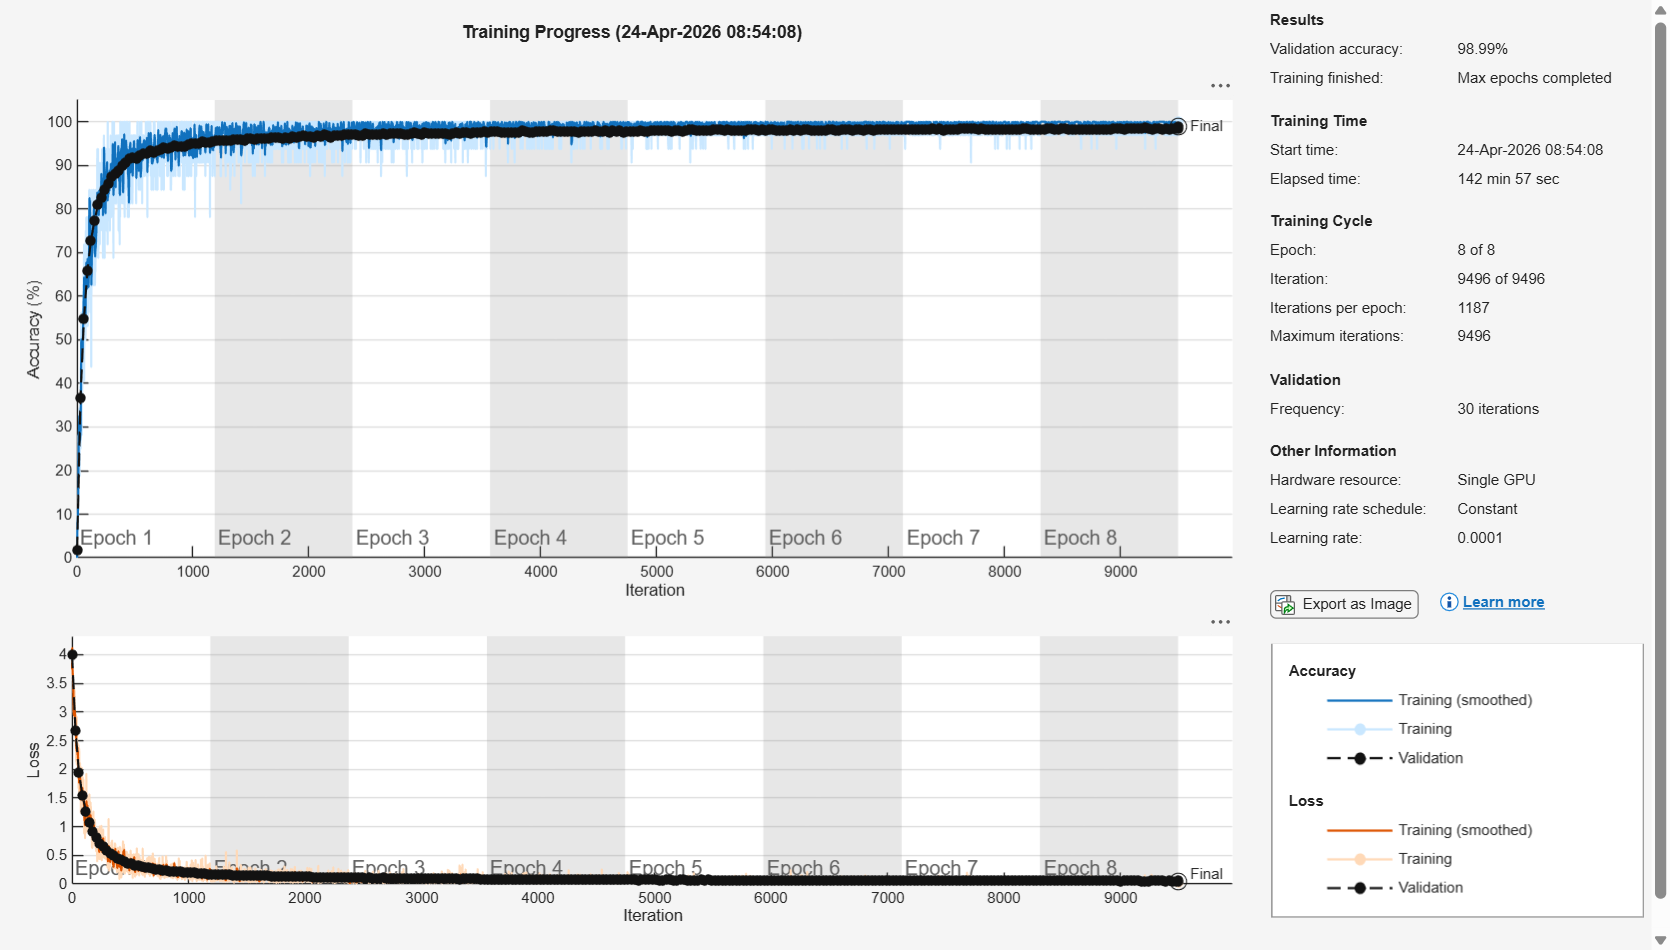

%% =========================
%% 4. RESNET50
%% =========================

net = resnet50;

lgraph = layerGraph(net);

% Number of classes
numClasses = numel(categories(imdsTrain.Labels));

% Replace final layers
newLayers = [
    fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10)
    softmaxLayer('Name','new_softmax')
    classificationLayer('Name','new_classoutput')
    ];

lgraph = replaceLayer(lgraph,'fc1000',newLayers(1));
lgraph = replaceLayer(lgraph,'fc1000_softmax',newLayers(2));
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newLayers(3));

% Resize data (ResNet requires 224x224)
augTrain_res = augmentedImageDatastore([224 224], imdsTrain);
augValidation_res = augmentedImageDatastore([224 224], imdsValidation);
augTest_res = augmentedImageDatastore([224 224], imdsTest);

%% Use SGDM (BEST for ResNet)

options_res = trainingOptions('adam',...
    'ExecutionEnvironment','gpu',...
    'InitialLearnRate',1e-4,...
    'MaxEpochs',8,...
    'MiniBatchSize',32,...
    'Shuffle','every-epoch',...
    'ValidationData',augValidation_res,...
    'ValidationFrequency',30,...
    'Plots','training-progress',...
    'Verbose',false);

% Train
[resNetModel,info] = trainNetwork(augTrain_res,lgraph,options_res);

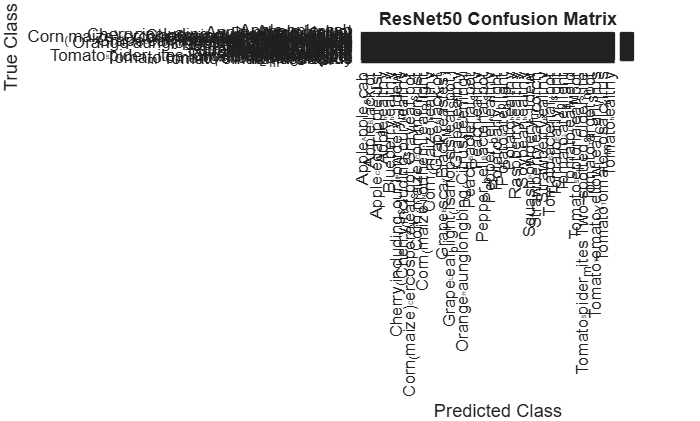

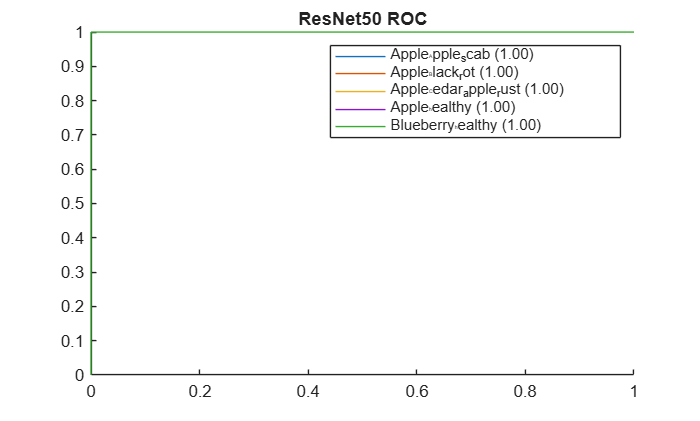

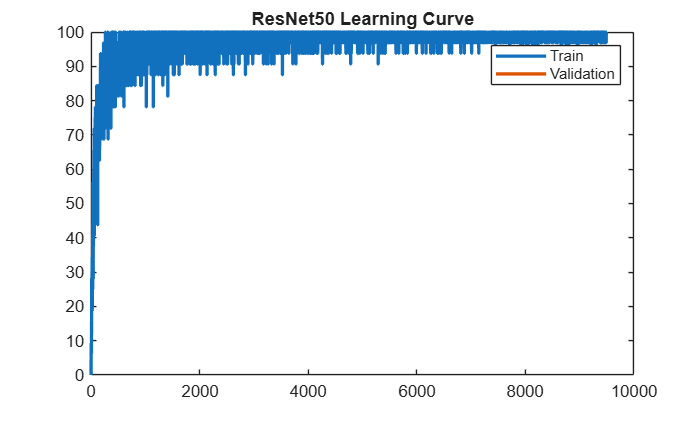


% Test
[YPred,scores] = classify(resNetModel,augTest_res);
YTest = imdsTest.Labels;

results.ResNet50 = evaluateModel(YPred,YTest,scores,'ResNet50',info);


% Save
save('ResNet50_Model.mat','resNetModel')

%% =========================
%% 🔧 EVALUATION FUNCTION
%% =========================

function result = evaluateModel(YPred,YTest,scores,name,info)

accuracy = mean(YPred == YTest);

confMat = confusionmat(YTest,YPred);
numClasses = size(confMat,1);

precision = zeros(numClasses,1);
recall = zeros(numClasses,1);
f1 = zeros(numClasses,1);

for i=1:numClasses
    TP = confMat(i,i);
    FP = sum(confMat(:,i)) - TP;
    FN = sum(confMat(i,:)) - TP;

    precision(i) = TP/(TP+FP+eps);
    recall(i) = TP/(TP+FN+eps);
    f1(i) = 2*(precision(i)*recall(i))/(precision(i)+recall(i)+eps);
end

figure('Name',[name ' Confusion Matrix'],'NumberTitle','off');

cm = confusionchart(YTest,YPred,'Normalization','row-normalized');
cm.Title = [name ' Confusion Matrix'];
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

% ROC (top 5 classes)
classes = categories(YTest);
figure; hold on;
for i=1:min(5,numel(classes))
    [X,Y,~,AUC] = perfcurve(YTest,scores(:,i),classes(i));
    plot(X,Y,'DisplayName',sprintf('%s (%.2f)',classes{i},AUC));
end
legend show; title([name ' ROC'])

% Learning curve
figure;
plot(info.TrainingAccuracy,'LineWidth',2); hold on;
plot(info.ValidationAccuracy,'LineWidth',2);
legend('Train','Validation');
title([name ' Learning Curve'])

result.accuracy = accuracy;
result.precision = mean(precision);
result.recall = mean(recall);
result.f1 = mean(f1);

end

models = fieldnames(results);
n = numel(models);

accuracy = zeros(n,1);

for i = 1:n
    accuracy(i) = results.(models{i}).accuracy;
end

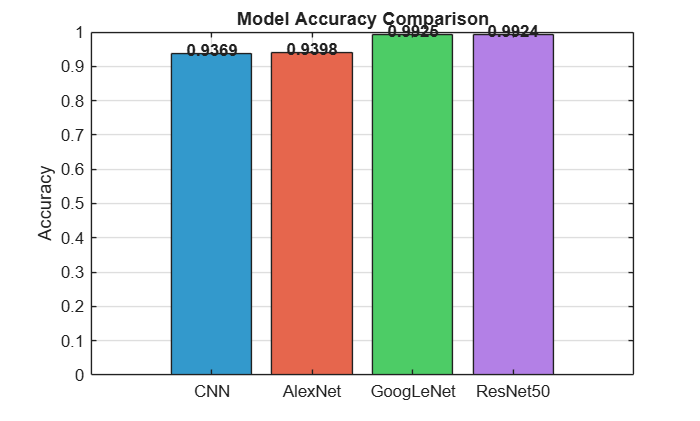

figure;

b = bar(accuracy);

% Assign different colors
b.FaceColor = 'flat';
colors = [
    0.2 0.6 0.8;   % CNN (blue)
    0.9 0.4 0.3;   % AlexNet (red)
    0.3 0.8 0.4;   % GoogLeNet (green)
    0.7 0.5 0.9;   % ResNet50 (purple)
];

b.CData = colors(1:length(accuracy),:);

set(gca,'XTickLabel',models)
title('Model Accuracy Comparison')
ylabel('Accuracy')
ylim([0 1])
grid on

% Add value labels on top of bars
for i = 1:length(accuracy)
    text(i, accuracy(i)+0.01, sprintf('%.4f', accuracy(i)), ...
        'HorizontalAlignment','center','FontWeight','bold');
end

models = fieldnames(results);
n = numel(models);

precision = zeros(n,1);
recall = zeros(n,1);
f1 = zeros(n,1);

for i = 1:n
    precision(i) = results.(models{i}).precision;
    recall(i) = results.(models{i}).recall;
    f1(i) = results.(models{i}).f1;
end

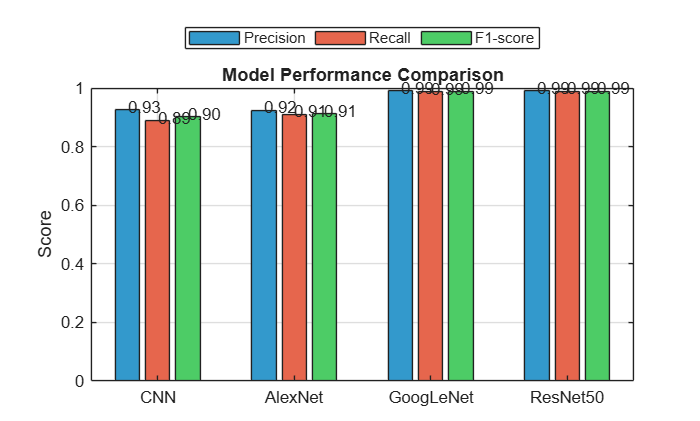

figure;

b = bar([precision recall f1]);

% Colors
b(1).FaceColor = [0.2 0.6 0.8]; % Precision
b(2).FaceColor = [0.9 0.4 0.3]; % Recall
b(3).FaceColor = [0.3 0.8 0.4]; % F1

set(gca,'XTickLabel',models)

legend('Precision','Recall','F1-score', ...
    'Location','northoutside', ...
    'Orientation','horizontal')

title('Model Performance Comparison')
ylabel('Score')
ylim([0 1])
grid on

% Value labels
for i = 1:length(models)
    text(i-0.22, precision(i)+0.01, sprintf('%.2f', precision(i)))
    text(i, recall(i)+0.01, sprintf('%.2f', recall(i)))
    text(i+0.22, f1(i)+0.01, sprintf('%.2f', f1(i)))
end

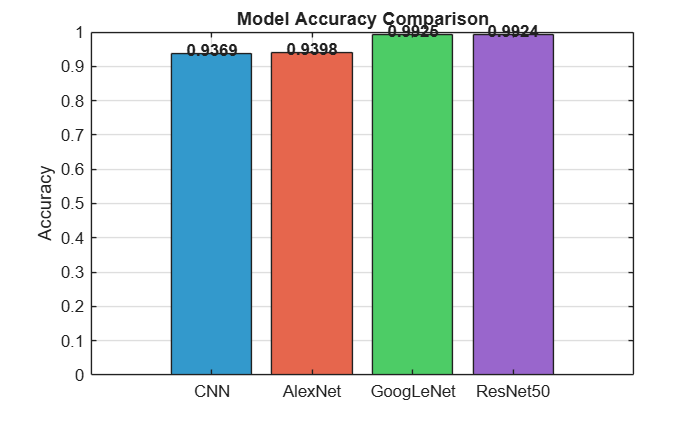

%% =========================
%% 📊 FINAL MODEL COMPARISON
%% =========================

models = {'CNN','AlexNet','GoogLeNet','ResNet50'};
n = numel(models);

accuracy = zeros(n,1);
precision = zeros(n,1);
recall = zeros(n,1);
f1 = zeros(n,1);

for i = 1:n
    accuracy(i) = results.(models{i}).accuracy;
    precision(i) = results.(models{i}).precision;
    recall(i) = results.(models{i}).recall;
    f1(i) = results.(models{i}).f1;
end

%% =========================
%% 🎨 1. ACCURACY GRAPH
%% =========================

figure;

b = bar(accuracy);

b.FaceColor = 'flat';
colors = [
    0.2 0.6 0.8;   % CNN
    0.9 0.4 0.3;   % AlexNet
    0.3 0.8 0.4;   % GoogLeNet
    0.6 0.4 0.8;   % ResNet50
    ];

b.CData = colors;

set(gca,'XTickLabel',models)
title('Model Accuracy Comparison')
ylabel('Accuracy')
ylim([0 1])
grid on

% Value labels
for i = 1:n
    text(i, accuracy(i)+0.01, sprintf('%.4f', accuracy(i)), ...
        'HorizontalAlignment','center','FontWeight','bold');
end

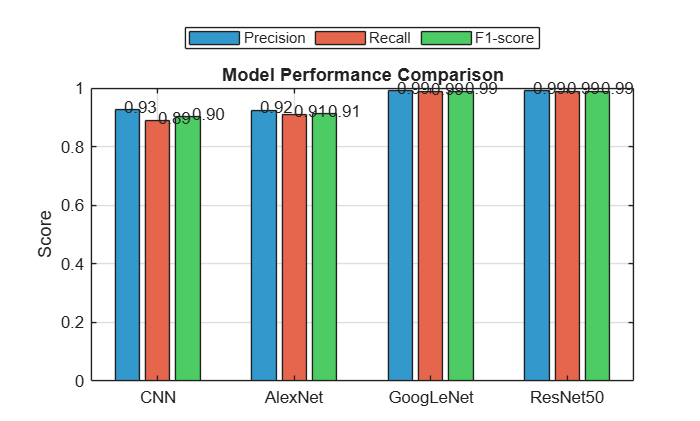


%% =========================
%% 📊 2. PRECISION / RECALL / F1
%% =========================

figure;

b = bar([precision recall f1]);

b(1).FaceColor = [0.2 0.6 0.8]; % Precision
b(2).FaceColor = [0.9 0.4 0.3]; % Recall
b(3).FaceColor = [0.3 0.8 0.4]; % F1

set(gca,'XTickLabel',models)

legend('Precision','Recall','F1-score', ...
    'Location','northoutside', ...
    'Orientation','horizontal')

title('Model Performance Comparison')
ylabel('Score')
ylim([0 1])
grid on

% Value labels
for i = 1:n
    text(i-0.25, precision(i)+0.01, sprintf('%.2f', precision(i)))
    text(i, recall(i)+0.01, sprintf('%.2f', recall(i)))
    text(i+0.25, f1(i)+0.01, sprintf('%.2f', f1(i)))
end


%% =========================
%% 📋 3. FINAL TABLE
%% =========================

finalTable = table(models', accuracy, precision, recall, f1, ...
    'VariableNames', {'Model','Accuracy','Precision','Recall','F1Score'});

disp('===== FINAL MODEL COMPARISON =====')

===== FINAL MODEL COMPARISON =====


disp(finalTable)

        Model        Accuracy    Precision    Recall     F1Score
    _____________    ________    _________    _______    _______

    {'CNN'      }    0.93689      0.92595     0.88857    0.90111
    {'AlexNet'  }    0.93984      0.92442     0.91111    0.91215
    {'GoogLeNet'}    0.99251      0.99044     0.98812    0.98916
    {'ResNet50' }    0.99239      0.99048     0.98837    0.98932



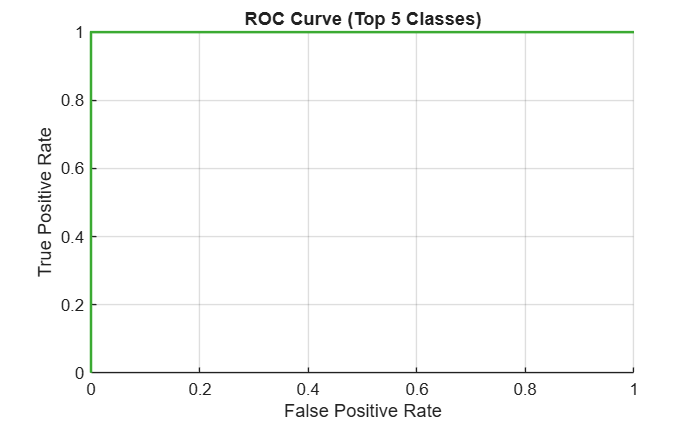

classes = categories(YTest);

figure('Name','ROC Curve','NumberTitle','off'); 
hold on;

for i = 1:min(5,numel(classes))
    [X,Y,~,~] = perfcurve(YTest, scores(:,i), classes(i));
    plot(X,Y,'LineWidth',1.5);
end

xlabel('False Positive Rate')
ylabel('True Positive Rate')
title('ROC Curve (Top 5 Classes)')
grid on

function [xi, meanY, meanAUC] = plotMacroROC(YTest, scores, modelName)

classes = categories(YTest);
numClasses = numel(classes);

xi = linspace(0,1,200);
allY = zeros(numClasses, numel(xi));
aucVals = zeros(numClasses,1);

for i = 1:numClasses
    [X,Y,~,AUC] = perfcurve(YTest,scores(:,i),classes(i));

    yi = interp1(X,Y,xi,'linear','extrap');

    allY(i,:) = yi;
    aucVals(i) = AUC;;

end

meanY = mean(allY,1);
meanAUC = mean(aucVals);

figure('Name',[modelName ' ROC'],'NumberTitle','off');
plot(xi,meanY,'LineWidth',3)
xlabel('False Positive Rate')
ylabel('True Positive Rate')
title([modelName ' Macro-Average ROC (AUC = ' num2str(meanAUC,'%.4f') ')'])
grid on

end